将yolov2的结果进行输出

clc;clear;close all;
workingPath = 'D:\deeplearning - diffraction'

workingPath = 'D:\deeplearning - diffraction'

% pic_path ='D:\deeplearning - diffraction\diffraction\Three';
% boundary_path = 'D:\deeplearning - diffraction\table';
% diffractionDataset=Generate_train(pic_path,boundary_path);
cd(workingPath)

load yolov2detector3
% numImages = height(diffractionDataset);
% f = waitbar(0,'开始搬运');
% for i = 1:numImages
%     I = imread(diffractionDataset.imageFilename{i});
%     [bboxes, scores, labels] = detect(detector, I);
%     I1=insertObjectAnnotation(I,'rectangle',bboxes,scores);
%     imwrite(I1,['D:\deeplearning - diffraction\detector_out\yolov2\',num2str(i,'%06d'),'.bmp']);
%     waitbar(i/numImages,f);
% end
% close(f)

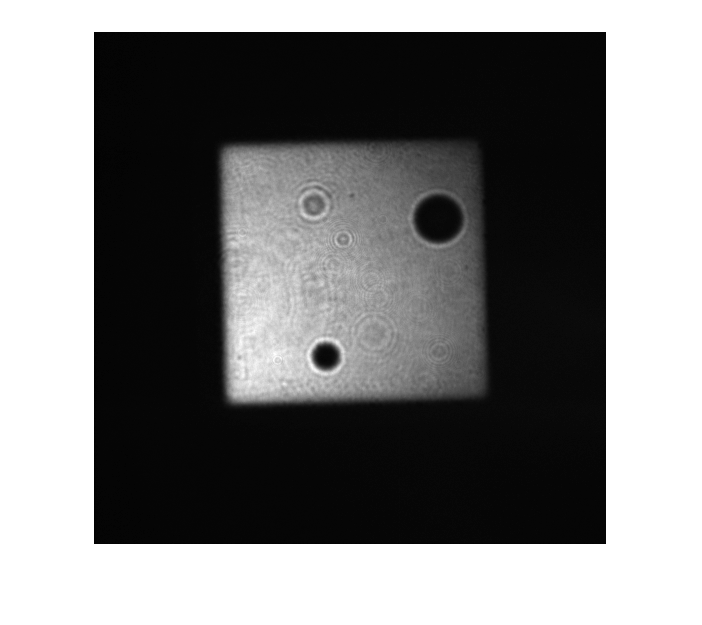

path = 'C:\Users\hp\Desktop\近场图\20190717004_FE_S.tif';
% path = '‪‪D:\下载\0010.png';
I0 = mat2gray(im2double(imread(path)));
figure,imshow(I0,[])

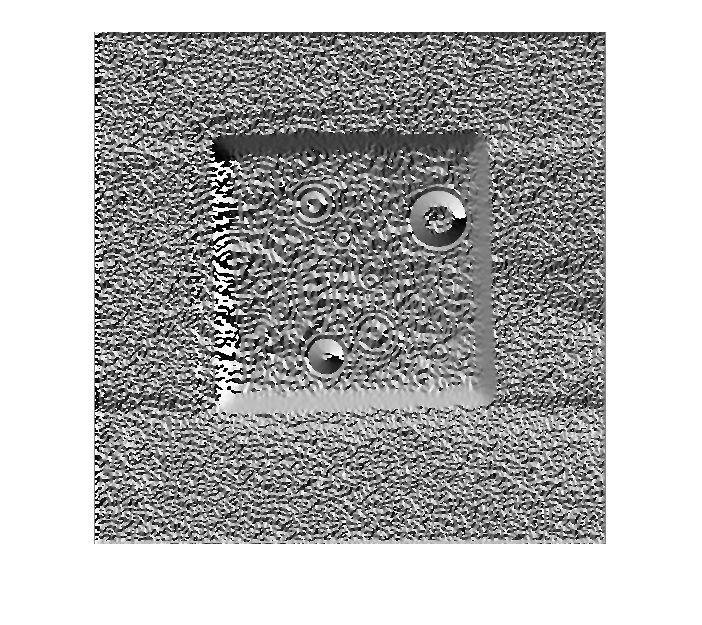

% I0 = (I0(1:1600,1:1600));
% I0 = imgaussfilt(I0,1);
% I0 = imnoise(I0,'gaussian',0,0.0001);
% I0 = imresize(I0,[256,256]);
I = I0;
    [u,s,v]=svd(I0);
    sval_nums = 2;
    low = 1;
    u1 =zeros(size(u));
    s1=u1;v1 =u1;
    u1(:,low:sval_nums) =u(:,low:sval_nums);
    s1(:,low:sval_nums) =s(:,low:sval_nums);
    v1(:,low:sval_nums) =v(:,low:sval_nums);
    I1 = u1*s1*v1';
    I1 = imgaussfilt(I1,20);
    I0 = (mat2gray(I./I1));
%     I = I0;
    I = imgaussfilt(I,1);
    %
    H = (fspecial('sobel'));
    dx = (imfilter(I,H,'circular','same'));
    dy = (imfilter(I,H','circular','same'));
    arrow = im2uint8 (mat2gray(atan2(dx,dy)));
    arrow = cat(3,arrow,arrow,arrow);
    
%      arrow = imread('D:\deeplearning - diffraction\diffraction\Three_write\70_48.bmp');
figure,imshow(arrow)

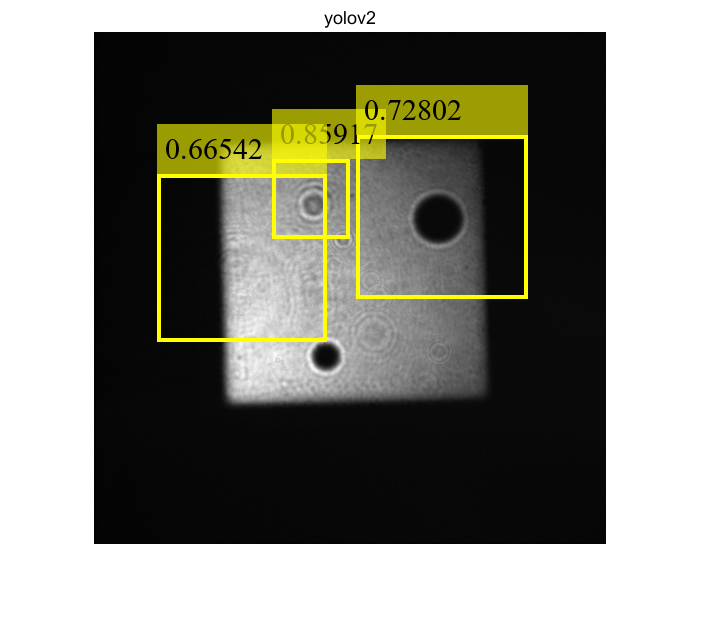

I = cat(3,I0,I0,I0);
I1 = mat2gray(im2double(imread(path)));

[bboxes, scores, labels] = detect(detector, arrow);
%bboxes = bboxes(scores>0.5,:)./255.*size(I1,1);
bboxes = bboxes(scores>0.5,:);
scores = scores(scores>0.5);

I1=insertObjectAnnotation(I1,'rectangle',bboxes,scores, 'LineWidth',4,'Font','Times New Roman', 'FontSize',30);

figure,imshow(I1),title('yolov2')

imwrite(I1,'yolov2out.bmp')

% load ('D:\deeplearning - diffraction\code\detector.mat')


% [bboxes, scores, labels] = detect(detector, I0);
% % bboxes = bboxes(scores>0.5,:);
% % scores = scores(scores>0.5);
% I1=insertObjectAnnotation(I0,'rectangle',bboxes,scores);
% figure,imshow(I1),title('fastrcnn')